mu_mesh = .375:.0625:.625;
sigma_mesh = .02:.005:.035;

x = 2;


% Simple Case: Submit Two Different Subjective Probabilities

for mu = mu_mesh
    for sigma = sigma_mesh
        focal_outcome = nan;
        compliment_outcome = nan;
        for lower_percentile = .01:.001:.49
            for higher_percentile = .51:.001:.99
                p1 = modified_beta_inverse_cdf(lower_percentile,mu,sigma);
                p1_matched = modified_beta_inverse_cdf(1-lower_percentile,mu,sigma); % Outside In Matching
                assert(p1_matched > p1)
                peer_bet1 = peer_to_peer(p1,p1_matched,1,x);

                p2 = modified_beta_inverse_cdf(higher_percentile,mu,sigma);
                p2_matched = modified_beta_inverse_cdf(1-higher_percentile,mu,sigma); % Outside In Matching
                assert(p2_matched < p2)
                peer_bet2 = peer_to_peer(p2,p2_matched,1,x);        

                % Check: Proper Win Conditions
                assert(~peer_bet1.player(1).win_condition)
                assert(peer_bet1.player(2).win_condition)
                
                % Binary Event Outcomes
                pot_amount1 = round(peer_bet1.player(1).bet_amount,2) + round(peer_bet1.player(2).bet_amount,2) - round(peer_bet1.profit,2);
                pot_amount2 = round(peer_bet2.player(1).bet_amount,2) + round(peer_bet2.player(2).bet_amount,2) - round(peer_bet2.profit,2); 
                stake_sum  = round(peer_bet1.player(1).bet_amount,2) + round(peer_bet2.player(1).bet_amount,2);

                focal_outcome = pot_amount2 - stake_sum;
                compliment_outcome = pot_amount1 - stake_sum;

                if focal_outcome > 0 && compliment_outcome > 0
                    fprintf('Arbitrage Possible for mu = %.4g and sigma = %.4g with p1 = %.4g and p2 = %.4g\n',mu,sigma,p1,p2)
                    fprintf('Profit = %.8g, Profitability = %.8g\n',min(focal_outcome,compliment_outcome),min(focal_outcome,compliment_outcome)/stake_sum);
                end
            end
        end
    end
end

fprintf('Done Checking for Arbitrage with Modified Beta')

Done Checking for Arbitrage with Modified Beta

Done Checking for Arbitrage with Modified Rayleigh

% Median of Modified Raleigh

B = .14

B = 0.1400

rayleigh_median = modified_rayleigh_inverse_cdf(.5,B)

rayleigh_median = 0.4648

fprintf('\n')

% Kentucky Windage

x = 0.25;
B = .14;

p1 = .31

p1 = 0.3100

p1_percentile = modified_rayleigh_cdf(p1,B)

p1_percentile = 0.0025

p1_matched = modified_rayleigh_inverse_cdf(1-p1_percentile,B) % Outside In Matching

p1_matched = 0.7823

assert(p1_matched > p1)
peer_bet1 = peer_to_peer(p1,p1_matched,100,x);

fprintf('  \n')


p2 = .47

p2 = 0.4700

p2_percentile = modified_rayleigh_cdf(p2,B)

p2_percentile = 0.5216

p2_matched = modified_rayleigh_inverse_cdf(1-p2_percentile,B) % Outside In Matching

p2_matched = 0.4597

assert(p2_matched < p2)
peer_bet2 = peer_to_peer(p2,p2_matched,95,x);

% Check: Proper Win Conditions
assert(~peer_bet1.player(1).win_condition)
assert(peer_bet2.player(1).win_condition)

% Binary Event Outcomes
pot_amount1 = round(peer_bet1.player(1).bet_amount,2) + round(peer_bet1.player(2).bet_amount,2) - round(peer_bet1.profit,2)

pot_amount1 = 174.7100

pot_amount2 = round(peer_bet2.player(1).bet_amount,2) + round(peer_bet2.player(2).bet_amount,2) - round(peer_bet2.profit,2)

pot_amount2 = 177.3400

stake_sum  = round(peer_bet1.player(1).bet_amount,2) + round(peer_bet2.player(1).bet_amount,2)

stake_sum = 166.4200


focal_outcome = (pot_amount2 - stake_sum)

focal_outcome = 10.9200

compliment_outcome = (pot_amount1 - stake_sum)

compliment_outcome = 8.2900

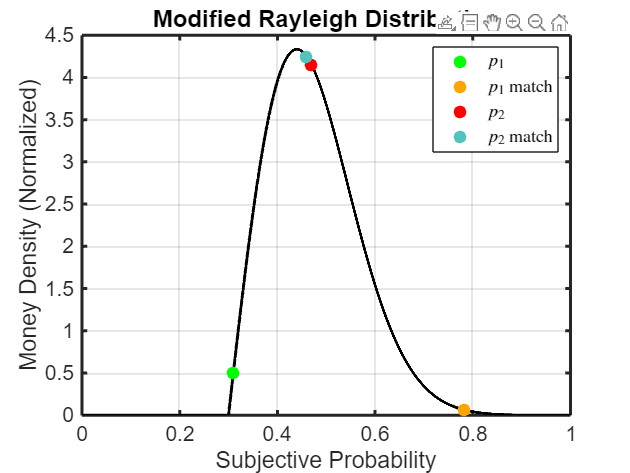


figure
plot(0:.0001:1,modified_rayleigh(0:.0001:1,B),"Color",[0 .0 0])
hold on
plot(p1,modified_rayleigh(p1,B),'Color',[0 1 0],'Marker','.','MarkerSize',25,'LineStyle','none')
plot(p1_matched,modified_rayleigh(p1_matched,B),'Color',[255 165 0]/255,'Marker','.','MarkerSize',25,'LineStyle','none')
plot(p2,modified_rayleigh(p2,B),'Color',[1 0 0],'Marker','.','MarkerSize',25,'LineStyle','none')
plot(p2_matched,modified_rayleigh(p2_matched,B),'Color',[83 195 189]/255,'Marker','.','MarkerSize',25,'LineStyle','none')
xlabel('Subjective Probability')
ylabel('Money Density (Normalized)')
title('Modified Rayleigh Distribution')
legend({'',sprintf('%s','$p_1$'),sprintf('%s','$p_1$ match'),sprintf('%s','$p_2$'),sprintf('%s','$p_2$ match')},'Interpreter','latex','FontSize',12)
sexy_plot
hold off

% Money Line Anchored Arbitrage
mu = .505;
sigma = .03;
x = 2;

subjective_probs = modified_beta_inverse_cdf(rand(1,1e3),mu,sigma);
bet_amounts = 5*ones(1,1e3); % Assuming Bet Amounts were Inedependent of Subjective Probability

subjective_probs(1) = .499;
bet_amounts(1) = 9.75;

[player_struct,~] = mark_1_gambling_system(subjective_probs,bet_amounts,x);
mark1_system_metrics = gambling_system_checker(player_struct,bet_amounts)

mark1_system_metrics = struct with fields:
             dollar_accountability: 1
                    peer_bets_work: 1
                   moneyline_works: 1
                  peer2peer_profit: 112.6000
                  moneyline_profit: 1.3100
                      total_profit: 113.9100
                     profit_margin: 0.0228
    subjective_expectation_created: 112.8974
                       effective_x: 1.9947
                  waste_proportion: 2.8373e-04
           subjective_expectations: [0.0750 0.0593 0.3891 0.1171 0.0555 0.0388 0.0447 0.1627 0.2821 0.0345 0.1385 0.0803 0.0525 0.1437 0.0878 0.0231 0.1362 0.2370 0.0985 0.1968 0.1175 0.0549 0.2036 0.0457 0.1424 0.2521 0.0781 0.0601 … ] (1×1000 double)
    subjective_standard_deviations: [0.0050 4.7596 4.5318 4.9368 4.8872 4.9083 4.7699 4.8877 4.7424 4.8050 4.9151 4.8498 4.7648 4.7930 4.8494 4.9189 4.9048 4.6748 4.9581 4.7179 4.9368 4.7498 4.8425 4.8875 4.9150 4.7896 4.8499 4.7546 … ] (1×1000 double)



p_alpha_values = [player_struct.moneyline_palpha];
player_struct(1)

ans = struct with fields:
               player_number: 1
          player_probability: 0.4990
    peer2peer_win_conditions: 0
       peer2peer_bet_amounts: 4.8900
              peer2peer_pots: 9.8300
             matched_players: 400
               match_numbers: 409
     moneyline_win_condition: 1
            moneyline_palpha: 0.4949
             moneyline_pbeta: NaN
          moneyline_earnings: 4.9600
        moneyline_bet_amount: 4.8600
             remaining_money: 0



bin_edges = [.4125:.005:.6125];
bin_peer_focal_bets = zeros(1,length(bin_edges)-1);
bin_peer_compliment_bets = zeros(1,length(bin_edges)-1);
bin_ml_focal_bets = zeros(1,length(bin_edges)-1);
bin_ml_compliment_bets = zeros(1,length(bin_edges)-1);
bin_remaining_bets = zeros(1,length(bin_edges)-1);

peer2peer_win_conditions = [player_struct(:).peer2peer_win_conditions];
peer2peer_bet_amounts = [player_struct(:).peer2peer_bet_amounts];
moneyline_win_conditions = [player_struct(:).moneyline_win_condition];
moneyline_bet_amounts = [player_struct(:).moneyline_bet_amount];
remaining_bet_amounts = [player_struct(:).remaining_money];

for index = 1:(length(bin_edges)-1)
    include_me = subjective_probs>=bin_edges(index) & subjective_probs<bin_edges(index+1);

    % Peer Bets
    included_peer2peer_win_conditions = peer2peer_win_conditions(include_me);
    included_peer2peer_bet_amounts = peer2peer_bet_amounts(include_me);

    bin_peer_focal_bets(index) = sum(included_peer2peer_win_conditions.*included_peer2peer_bet_amounts);
    bin_peer_compliment_bets(index) = sum(~included_peer2peer_win_conditions.*included_peer2peer_bet_amounts);   

    % Money Lines
    included_moneyline_win_conditions = moneyline_win_conditions(include_me);
    included_moneyline_bet_amounts = moneyline_bet_amounts(include_me);

    included_moneyline_bet_amounts = included_moneyline_bet_amounts(~isnan(included_moneyline_win_conditions));
    included_moneyline_win_conditions = included_moneyline_win_conditions(~isnan(included_moneyline_win_conditions));

    bin_ml_focal_bets(index) = sum(included_moneyline_win_conditions.*included_moneyline_bet_amounts);
    bin_ml_compliment_bets(index) = sum(~included_moneyline_win_conditions.*included_moneyline_bet_amounts);   

    bin_remaining_bets(index) = sum(remaining_bet_amounts(include_me));
end

bin_matrix = [bin_peer_compliment_bets; bin_peer_focal_bets; bin_ml_compliment_bets; bin_remaining_bets; bin_ml_focal_bets];

sum(bin_matrix,"all")

ans = 4.9998e+03

sum(bet_amounts)+5*sum(subjective_probs<bin_edges(1) | subjective_probs>=bin_edges(end))

ans = 5.0098e+03

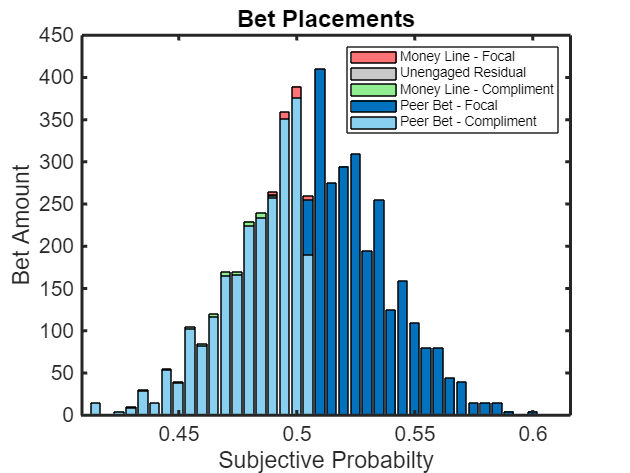


bin_colors = [137/255 207/255 240/255; 0 0.4470 0.7410; 144/255 238/255 144/255; 200/255 200/255 200/255; 1 114/255 118/255];
x_values = .415:.005:.61;
bh = bar(x_values,bin_matrix,'stacked');
set(bh, 'FaceColor', 'Flat')
bh(1).CData = bin_colors(1,:);
bh(2).CData = bin_colors(2,:);
bh(3).CData = bin_colors(3,:);
bh(4).CData = bin_colors(4,:);
bh(5).CData = bin_colors(5,:);
legend({'Peer Bet - Compliment','Peer Bet - Focal','Money Line - Compliment','Unengaged Residual', 'Money Line - Focal'})
xlabel('Subjective Probabilty')
ylabel('Bet Amount')
title('Bet Placements')
sexy_plot
grid off